## Power of N

### Single simulation in burst mode (pure estimation)


 ===== CONDITIONS ======
Number of transmitted bits per burst = 100

Number of simulations (1 burst per simulation) = 1000

Carrier frequency [MHz] = 450.00

Doppler (constant) [Hz] = 10000.00

Rb = 1000000
Eb/N0: 6.99 dB 
Es/N0: 10.00 dB 

 ===== RESULTS ======
Mean of the estimation (normalized  to Rs): 0.020184

Variance of the estimation (normalized to Rs): 0.000148


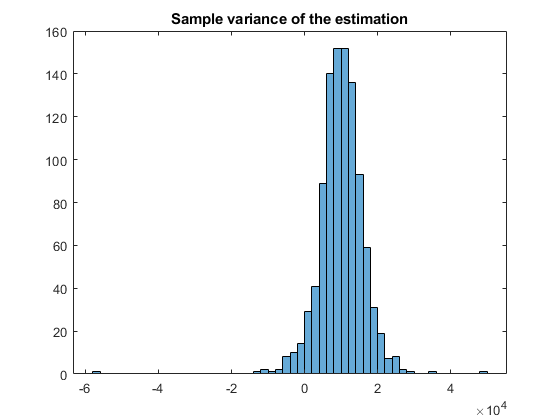

tic
simulate3(5,450e6,1e6,true,false,100,1e3,10e3);

toc

Elapsed time is 1.652235 seconds.


### Plotting of variance with respect to SNR

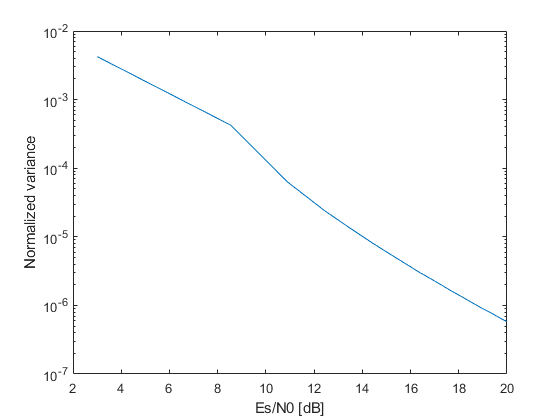

clc;
clear all;

tic

N= 20; %Number of EbN0 points
EbN0 = linspace(1,50,N); 

var = zeros(1,N);
for k=1:N
    var(1,k) = simulate3(EbN0(1,k),450e6,1e6,false,false,100,1e5,10e3);
end
EsN0 = 2* EbN0;
EsN0_dB = 10*log10(EsN0);

save('SNR_VARIANCE.mat');
figure;
semilogy(EsN0_dB,var);
xlabel('Es/N0 [dB]');
ylabel('Normalized variance');

toc

Elapsed time is 2310.753341 seconds.
